# Métodos númericos para valoración de opciones

Andrés Felipe Parra Méndez - Emanuel Serna Ruales - Samuel Andrés Areiza Tabares

Procesos Estocásticos II

Freddy H. Marín Sánchez

Universidad EAFIT. 2025

clear all
clc

### 1. Activo a modelar como Movimiento Browniano Geómetrico (MBG)

####     1.1. Visualización y descripción

T = readtable('datos.xlsx')

T = 502×35 table
       Date         ABT       AEP       AIG       AMT       ATO       CSX        DE       DUK        ED        ES       GIS        HD        KO        KR       LOW       MCD       MDLZ      MLM       NVDA       O        PEP       PFE       PNC       PSA       SHW        SO       TFC       TJX       USB       VMC       WEC       WMB       XLU       YUM  
    ___________

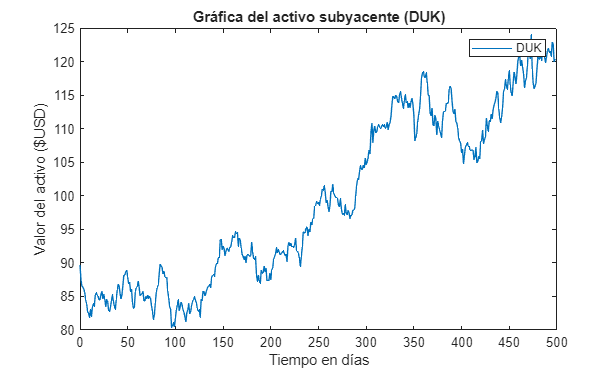

X = T.DUK(1:499);
dt = 1/252;
N = length(X);

figure
plot(0:1:N-1,X)
xlabel("Tiempo en días")
ylabel("Valor del activo ($USD)")
legend("DUK")
title("Gráfica del activo subyacente (DUK)")

####  1.2. Verificación

% Paso 0: Descripción estadística del activo
EstadX = [min(X) max(X) mean(X) median(X) mode(X) var(X) std(X) kurtosis(X) skewness(X)]

EstadX =    80.4050  124.0500   99.2826   97.0851   83.4540  162.1753   12.7348    1.5919    0.2385


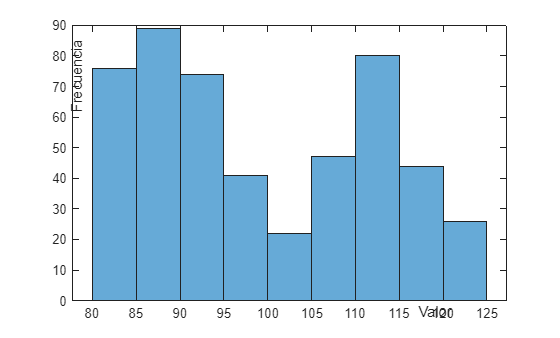

% Histograma
histogram(X)
title('Histograma de los valores del activo DUK')
xlabel('Valor')
ylabel('Frecuencia')

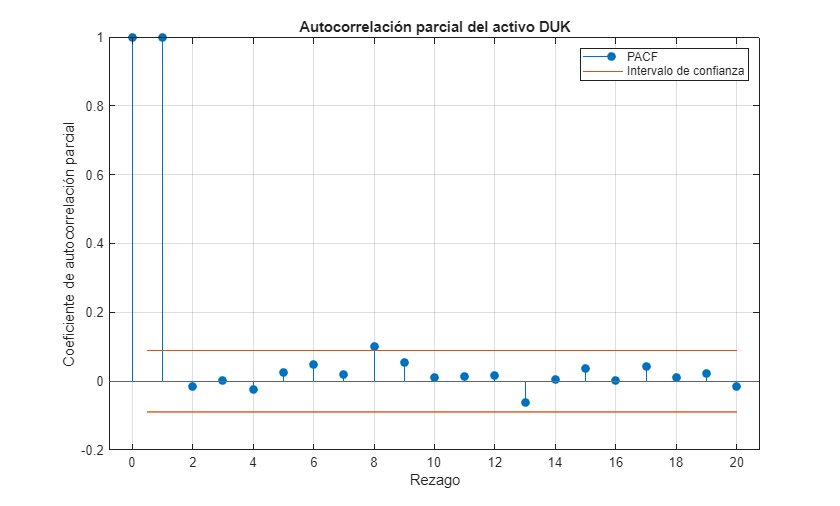

% Paso 1: Autocorralación Parcial
parcorr(X)
title('Autocorrelación parcial del activo DUK');
xlabel('Rezago');
ylabel('Coeficiente de autocorrelación parcial');
legend('PACF', 'Intervalo de confianza', 'Location', 'northeast');

% Paso 2: Dimensión Fractal y exponente de Hurst
DF = fractalvol(X); % Cálculo de la dimension fractal
EH = genhurst(X); % Cálculo del exponente de Hurst 
S = DF + EH; % Debe ser igual a 2
Z = [DF EH S]

Z =     1.4136    0.4731    1.8867


% 1 < DF < 1.5 para ser un proceso de tendencia

% Paso 3: Análisis de los retornos instantáneos
R = (X(2:N) - X(1:N-1)) ./ X(1:N-1);

archtest(R)

ans = logical
   0


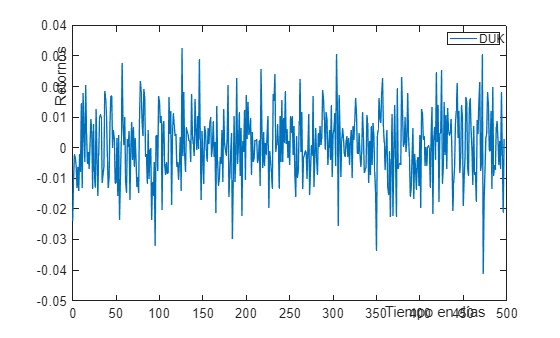

figure
plot(0:1:N-2,R) % Gráfica de los retornos instantáneos del activo
xlabel('Tiempo en días')
ylabel('Retornos')
legend('DUK')
title('Retornos Instantáneos del activo subyacente')

% Descripción estadística de los retornos
EstadR = [min(R) max(R) mean(R) median(R) mode(R) var(R) std(R) kurtosis(R) skewness(R)]

EstadR =    -0.0413    0.0325    0.0007    0.0008   -0.0413    0.0001    0.0110    3.3179   -0.0924


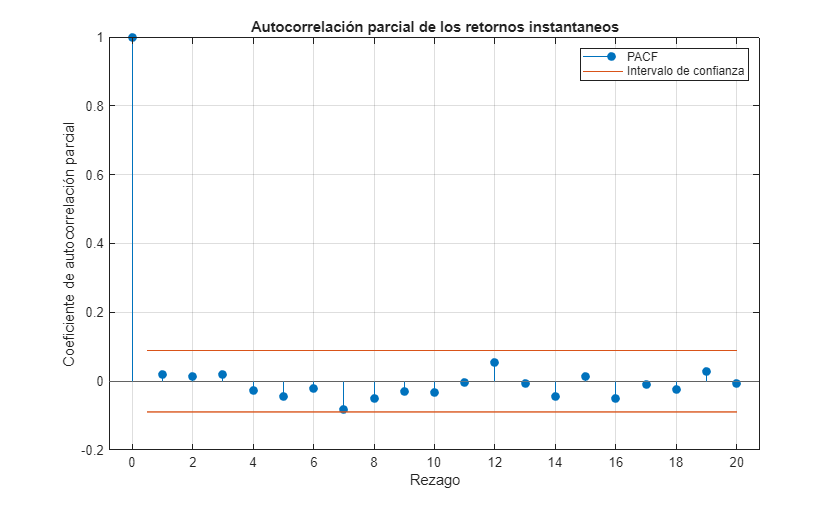

parcorr(R) % Lo retornos no deben estar correlacionados
title('Autocorrelación parcial de los retornos instantaneos');
xlabel('Rezago');
ylabel('Coeficiente de autocorrelación parcial');
legend('PACF', 'Intervalo de confianza', 'Location', 'northeast');

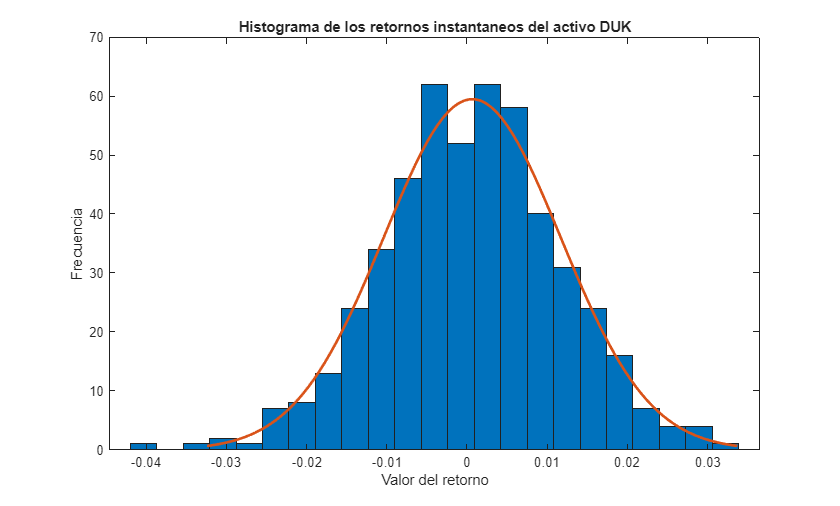


figure
histfit(R) % Verificación visual de que los retornos siguen una distribución normal
title('Histograma de los retornos instantaneos del activo DUK')
xlabel('Valor del retorno')
ylabel('Frecuencia')

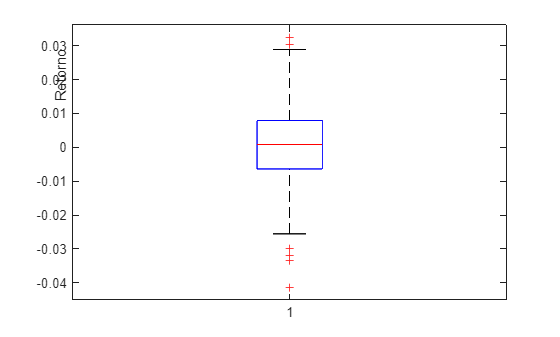

figure 
boxplot(R) % Se pueden quitar hasta un 5% de los outliers para tests
title('Diagrama de caja de los retornos del activo DUK')
ylabel('Retorno')

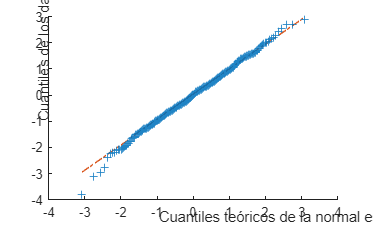

% Paso 4: Pruebas de normalidad para los retornos
m = mean(R);
des = std(R);
Z = (R-m)/des; % Retornos normalizados para el QQ-Plot y la prueba ktest
qqplot(Z); % Comparación Normal Estándar
title('Gráfico Q-Q de los retornos normalizados');
xlabel('Cuantiles teóricos de la normal estándar');
ylabel('Cuantiles de los datos');

% Se quiere que los tests devuelvan 0, con lo cual no se rechaza la hipótesis 
% nula de que los retornos siguen una distribución normal

% Test de Jarque-Bera
[h_jb, p_jb] = jbtest(R);

% Test de Kolmogorov-Smirnov
[h_ks, p_ks] = kstest(Z); % Z ya está normalizado

% Test de Anderson-Darling
[h_ad, p_ad] = adtest(R);

% Test de Lilliefors
[h_lillie, p_lillie] = lillietest(R);


% Vector de resultados
PNorRet = [h_jb, h_ks, h_ad, h_lillie];
Pvalores = [p_jb, p_ks, p_ad, p_lillie];

% Mostrar resultados
% Resultados de los test de normalidad (0 = no se rechaza H0):
disp(array2table(PNorRet, 'VariableNames', {'JarqueBera','KolmogorovSmirnov','AndersonDarling','Lilliefors'}));

    JarqueBera    KolmogorovSmirnov    AndersonDarling    Lilliefors
    __________    _________________    _______________    __________

        0                 0                   0               0     



% P-valores de los test de normalidad:
disp(array2table(Pvalores, 'VariableNames', {'JarqueBera','KolmogorovSmirnov','AndersonDarling','Lilliefors'}));

    JarqueBera    KolmogorovSmirnov    AndersonDarling    Lilliefors
    __________    _________________    _______________    __________

     0.22016           0.9802              0.80846           0.5    



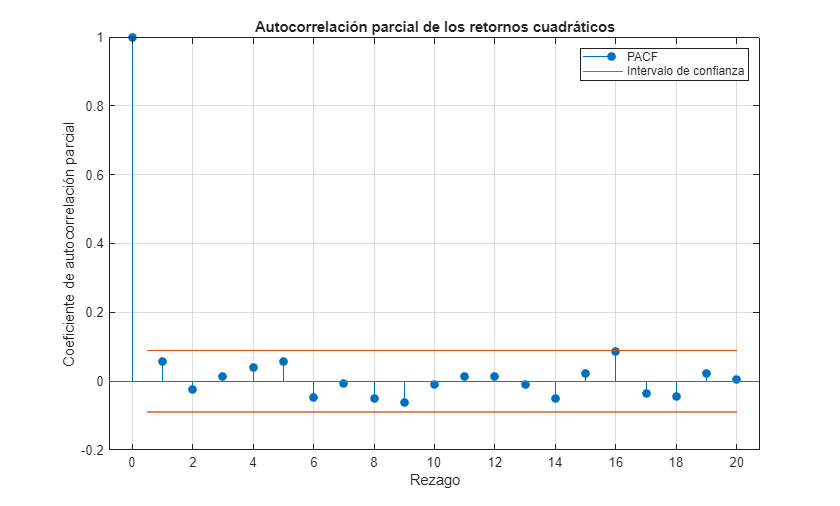

% Paso 5: Prueba volatilidad constante

% Efectos ARCH
R2 = R.^2;
parcorr(R2)
title('Autocorrelación parcial de los retornos cuadráticos');
xlabel('Rezago');
ylabel('Coeficiente de autocorrelación parcial');
legend('PACF', 'Intervalo de confianza', 'Location', 'northeast');

% ARCH Test
res = R - mean(R);
h = archtest(res);  % Se quiere que devuelva 0 ya que así no rechaza la hipotesis nula,
                    % por tanto, no hay heterocedasticidad
[h, pvalue, stat, cValue] = archtest(R)

h = logical
   0


pvalue = 0.2094

stat = 1.5755

cValue = 3.8415


% Test de White
% Asegurarse que R es vector columna
R = R(:);

% a) Regresión auxiliar con términos no lineales
T = length(R);
X1 = [(1:T)', (1:T)'.^2]; % Variables independientes (tiempo y cuadrado del tiempo)
[b, ~, resid] = regress(R, [ones(T,1), X1]);

% b) Construir regresión auxiliar
X_white = [X1, X1(:,2).^2];
[~, ~, resid_aux] = regress(resid.^2, X_white);

% c) Estadístico de prueba
R2 = 1 - sum(resid_aux.^2) / sum((resid.^2 - mean(resid.^2)).^2);
chi2_stat = T * R2;
pval = 1 - chi2cdf(chi2_stat, size(X_white,2)-1);

disp(['p-valor: ', num2str(pval)])

p-valor: 1


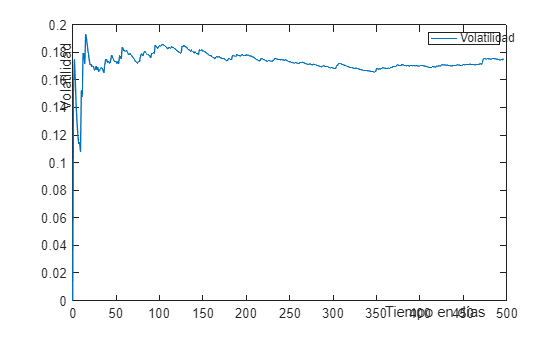

% Prueba Gráfica Empírica
for j=2:N-1
    VE(j) = std(R(1:j)) / sqrt(dt);
end

% La varianza se debe estabilizar rápido si hay homocedesticidad
figure
plot(0:1:N-2,VE)
xlabel('Tiempo en días')
ylabel('Volatilidad')
legend('Volatilidad')
title('Volatilidad acumulada del subyacente')

vol=VE(end)

vol = 0.1750

% Paso 6: Estimación de parámetros
muest = mean(R)/dt;
sigmaest = sqrt(var(R)/dt);
Est = [muest sigmaest]

Est =     0.1643    0.1750


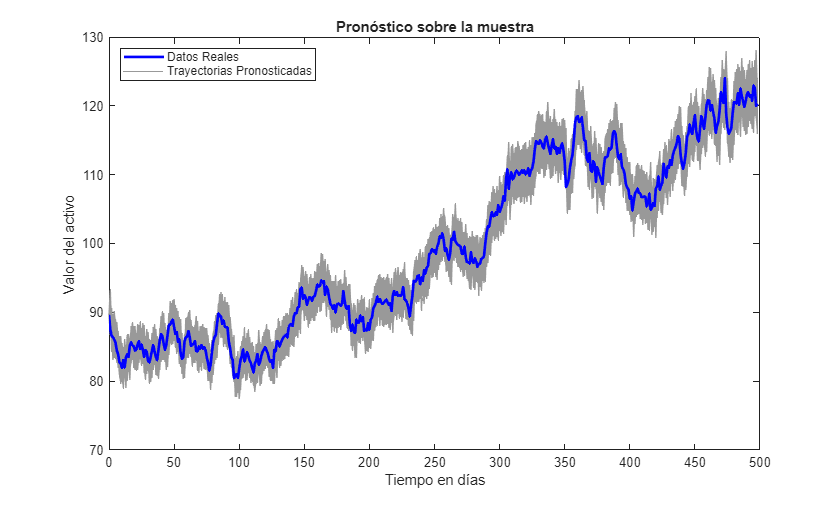

% Paso 7: Prónostico sobre la muestra
rng(01062025)
ra = randn(1,N-1);
k = 1000;
XP(1) = X(1);

for i=1:k
    XP(i,1) = X(1);
end

for i=1:k
    for j=2:N
        XP(i,j) = X(j-1) + muest*X(j-1)*dt + sigmaest*X(j-1)*sqrt(dt)*randn; 
    end
end

% Primero graficamos las trayectorias (gris)
h2 = plot(0:1:N-1, XP, 'Color', [0.6 0.6 0.6], 'LineWidth', 0.5); % Trayectorias grises
hold on;

% Luego graficamos la serie real (azul)
h1 = plot(0:1:N-1, X, 'b-', 'LineWidth', 2); % Serie real en azul
hold off;

xlabel('Tiempo en días');
ylabel('Valor del activo');
title('Pronóstico sobre la muestra');
legend([h1, h2(1)], {'Datos Reales', 'Trayectorias Pronosticadas'}, 'Location', 'northwest'); % Usamos solo una de XP

% Calcular el mape con todos los pronósticos y sacar estadísticos
m1=mape(X,XP');
Estm1=[min(m1) mean(m1) median(m1) max(m1)]

Estm1 =     1.1142    1.2362    1.2357    1.3557


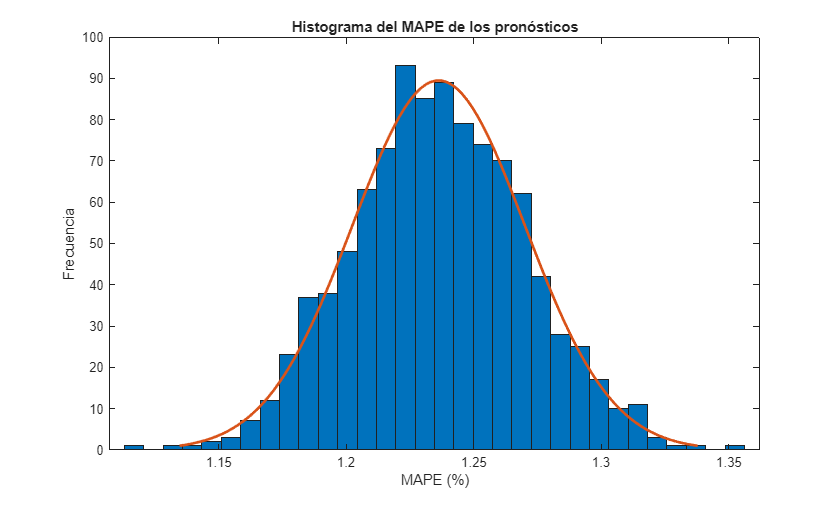

histfit(m1)
title('Histograma del MAPE de los pronósticos')
xlabel('MAPE (%)')
ylabel('Frecuencia')

####     1.3. Prónostico para precios de ejercicio:

Generar trayectorias a partir del último punto de la serie: 

%% Parámetros de simulación
num_trayectorias = 10000;  % Número de trayectorias a simular
periodos_simulacion = [252, 126, 84, 63];  % Horizontes temporales (1 año, 6m, 4m, 3m)
dt = 1/252;  % Paso de tiempo (1 día)
rng(01062025) % Semilla aleatoria

%% Inicialización de trayectorias
ultimo_valor = X(end);  % Último valor de la serie histórica
XP = repmat(ultimo_valor, num_trayectorias, 1);  % Matriz de trayectorias

% Generación de trayectorias futuras
for j = 2:periodos_simulacion(1)
    XP(:,j) = XP(:,j-1) .* (1 + muest * dt + sigmaest * sqrt(dt) * randn(num_trayectorias, 1));
end

S_i = XP(:, periodos_simulacion);  % Extraer los valores en los puntos de interés

% Calcular los valores de K para cada T_i
min_S_i = min(S_i);
max_S_i = max(S_i);
K_values = cellfun(@(minVal, maxVal) linspace(minVal, maxVal, 5)', ...
                  num2cell(min_S_i), num2cell(max_S_i), 'UniformOutput', false);

% Crear una matriz con los valores de K en columnas
K_matrix = cell2mat(K_values);

% Crear una tabla con los resultados
K_table = array2table(K_matrix, ...
    'VariableNames', {'T_1', 'T_1/2', 'T_1/3', 'T_1/4'}, ...
    'RowNames', {'Kmin', 'K_2', 'K_3', 'K_4', 'Kax'});

disp(K_table);

             T_1      T_1/2     T_1/3     T_1/4 
            ______    ______    ______    ______

    Kmin    66.712    81.366    86.761    83.055
    K_2     116.31    115.22    109.93     105.3
    K_3     165.91    149.07    133.09    127.55
    K_4     215.52    182.91    156.26    149.79
    Kax     265.12    216.76    179.43    172.04



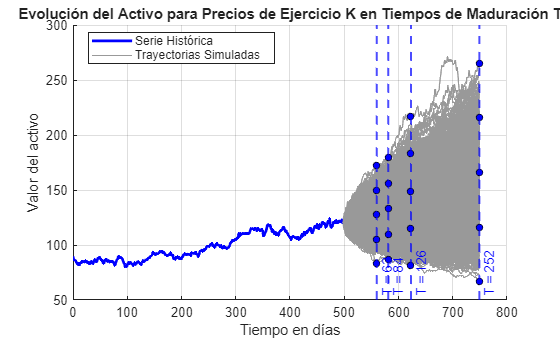

% Gráfico de la serie original y todas las trayectorias
figure;
hold on;

% Serie histórica en azul y gruesa
plot(0:length(X)-1, X, 'b-', 'LineWidth', 2);  

% Graficar todas las trayectorias simuladas en gris claro y delgadas
for i = 1:num_trayectorias
    plot(length(X)-1:length(X)+periodos_simulacion(1)-2, XP(i, :), ...
        'Color', [0.6 0.6 0.6], 'LineWidth', 0.2); % gris claro, línea delgada
end

% Añadir líneas verticales en los tiempos T
for i = 1:length(periodos_simulacion)
    xline(length(X)-1 + periodos_simulacion(i) - 1, '--b', ...
        ['T = ', num2str(periodos_simulacion(i))], ...
        'LabelVerticalAlignment', 'bottom', 'LineWidth', 1.5);
end

% Marcar los precios K en los tiempos correspondientes
for i = 1:length(periodos_simulacion)
    for j = 1:5
        tiempo = length(X) - 1 + periodos_simulacion(i) - 1; 
        valor = K_values{i}(j);
        plot(tiempo, valor, 'o', 'MarkerSize', 5, ...
            'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'b');
    end
end

xlabel('Tiempo en días');
ylabel('Valor del activo');
title('Evolución del Activo para Precios de Ejercicio K en Tiempos de Maduración T');
legend('Serie Histórica', 'Trayectorias Simuladas', 'Location', 'Best');
grid on;

### 2. Métodos para valoración de una opción call europea.

####     2.1. Funciones de los métodos numéricos

function BS = Black_Scholes(S0, K, r, sigma, T)
    R = (r + (sigma^2) / 2);
    d1 = (1 / (sigma * sqrt(T))) * (log(S0 / K) + R * T);
    d2 = d1 - sigma * sqrt(T);
    N1 = normcdf(d1);
    N2 = normcdf(d2);
    BS = S0 * N1 - exp(-r * T) * K * N2;
end

function IntervaloMC = MonteCarlo(S0, K, r, sigma, T, W, k, m)
    dt = T/m;               % Paso temporal
    M1 = zeros(W, 1);       % Almacena los precios simulados

    for n = 1:W
        % Números aleatorios estándar normales para las trayectorias
        rn = randn(k, m);

        % Inicializar matriz de precios
        S1 = zeros(k, m+1);
        S1(:, 1) = S0;

        % Simulación de trayectorias
        for j = 2:m+1
            S1(:, j) = S1(:, j-1) + r * S1(:, j-1) * dt + sigma * S1(:, j-1) .* sqrt(dt) .* rn(:, j-1);
        end

        % Precios finales
        Strike1 = S1(:, end);

        % Valor de la opción tipo Call
        f1 = exp(-r * T) * max(Strike1 - K, 0);

        % Guardar la media de esta simulación
        M1(n) = mean(f1);
    end

    % Calcular mínimo, media y máximo
    mi = min(M1);
    MMC = mean(M1);
    ms = max(M1);

    % Retornar vector con los tres valores
    IntervaloMC = [mi, MMC, ms];
end

function BT = arbol_binomial(S0, K, r, sigma, T, n)
    dt = T / n;                     % Paso temporal
    u = exp(sigma * sqrt(dt));      % Factor de ascenso 
    d = 1 / u;                      % Factor de descenso
    disc = exp(-r * dt);            % Factor de descuento por periodo

    % Probabilidad neutral al riesgo ajustada
    p = 0.5 + (r - 0.5 * sigma^2) * sqrt(dt) / (2 * sigma); 

    % Generar precios posibles al vencimiento
    j = (0:n)';                     % Índices de nodos
    SF = S0 * u.^j .* d.^(n - j);

    % Payoff de opción tipo Call
    Opt = max(SF - K, 0);

    % Proceso hacia atrás para descontar el valor
    for t = n:-1:1
        Opt = disc * ((1 - p) * Opt(1:t) + p * Opt(2:t+1));
    end

    % Precio estimado de la opción al tiempo 0
    BT = Opt(1);
end

function DF = diferencias_finitas(S0, ds, K, r, sigma, T)
    % Parámetros de la malla
    S_max = 2 * K;                    % Valor máximo en el dominio numérico
    ns = round(S_max / ds);           % Número de nodos en el eje del precio
    dtp = (ds / (sigma * S_max))^2;   % Incremento de prueba para el tiempo
    nt = ceil(T / dtp);               % Número de nodos en el tiempo
    dt = T / nt;                      % Incremento temporal ajustado

    % Vector de precios del activo subyacente
    S = linspace(0, S_max, ns + 1);
    % Inicialización de la malla para la opción
    MO = zeros(nt + 1, ns + 1);
    % Condición de frontera superior (Call)
    MO(:, end) = S_max - K;
    % Condición inicial al vencimiento (payoff)
    MO(end, :) = max(S - K, 0);

    % Cálculo de coeficientes del método explícito
    alpha = dt / (1 + r * dt);
    idx = 0:ns;
    a = alpha * ((-0.5 * r * idx) + 0.5 * sigma^2 * idx.^2);
    b = alpha * (1 / dt - sigma^2 * idx.^2);
    c = alpha * ((0.5 * r * idx) + 0.5 * sigma^2 * idx.^2);

    % Esquema de diferencias finitas 
    for i = nt:-1:1
        MO(i, 2:ns) = a(2:ns) .* MO(i+1, 1:ns-1) + ...
                      b(2:ns) .* MO(i+1, 2:ns) + ...
                      c(2:ns) .* MO(i+1, 3:ns+1);
    end

    % Encontramos el valor en la malla más cercano a S0
    pos_S0 = round(S0 / ds) + 1;
    DF = MO(1, pos_S0);
end

####     2.2. Cálculo del valor de la opción para los cuatro métodos

% Parámetros generales
S0 = X(end);             % Precio actual del activo
r = 0.05;                % Tasa de interés libre de riesgo
sigma = sigmaest;        % Volatilidad constante
T = [1, 1/2, 1/3, 1/4];  % Periodos de maduración (en años)
rng(01062025)            % Semilla aleatoria


% Parámetros para simulación Monte Carlo
W = 1000;    % Número de repeticiones 
k = 10000;   % Número de trayectorias por repetición
m = 500;     % Número de subdivisiones (para dt)

% Parámetro para árbol binomial 
n = 1000;    % Número de periodos

% Parámetro para diferencias finitas
ds = S0/1000;    % Incremento en el precio (una milesima parte del precio inicial)

result_tables = cell(length(T), 1);

for t = 1:length(T)
    T_actual = T(t);
    K_values_t = K_values{t}; 

    % Inicializar vectores para resultados y tiempos
    F_values = zeros(length(K_values_t), 1);
    MC_means = zeros(length(K_values_t), 1);
    MC_mins = zeros(length(K_values_t), 1);
    MC_maxs = zeros(length(K_values_t), 1);
    BT_values = zeros(length(K_values_t), 1);
    DF_values = zeros(length(K_values_t), 1);

    % Tiempos de cómputo (en segundos)
    time_BS = zeros(length(K_values_t), 1);
    time_MC = zeros(length(K_values_t), 1);
    time_BT = zeros(length(K_values_t), 1);
    time_DF = zeros(length(K_values_t), 1);

    for i = 1:length(K_values_t)
        K = K_values_t(i);

        % Black-Scholes
        tic;
        F_values(i) = Black_Scholes(S0, K, r, sigma, T_actual);
        time_BS(i) = toc;

        % Monte Carlo
        tic;
        IntervaloMC = MonteCarlo(S0, K, r, sigma, T_actual, W, k, m);
        time_MC(i) = toc;
        MC_mins(i) = IntervaloMC(1);
        MC_means(i) = IntervaloMC(2);
        MC_maxs(i) = IntervaloMC(3);

        % Árbol Binomial
        tic;
        BT_values(i) = arbol_binomial(S0, K, r, sigma, T_actual, n);
        time_BT(i) = toc;

        % Diferencias Finitas
        tic;
        DF_values(i) = diferencias_finitas(S0, ds, K, r, sigma, T_actual);
        time_DF(i) = toc;
    end

    % Crear tabla de resultados
    result_table = table(K_values_t, F_values, MC_mins, MC_means, MC_maxs, ...
                         BT_values, DF_values, time_BS, time_MC, time_BT, time_DF, ...
        'VariableNames', {'K', 'Black_Scholes', 'MC_Min', 'MC_Mean', 'MC_Max', ...
                          'Arbol_Binomial', 'Diferencias_Finitas', ...
                          'Tiempo_BS_s', 'Tiempo_MC_s', 'Tiempo_BT_s', 'Tiempo_DF_s'});

    result_tables{t} = result_table;

    % Mostrar resultados por consola
    fprintf('\n\nResultados para T = %.2f años:\n\n', T_actual);
    disp(result_table);
    fprintf('\n\n');
end



Resultados para T = 1.00 años:



      K       Black_Scholes    MC_Min      MC_Mean       MC_Max      Arbol_Binomial    Diferencias_Finitas    Tiempo_BS_s    Tiempo_MC_s    Tiempo_BT_s    Tiempo_DF_s
    ______    _____________    _______    __________    _________    ______________    ___________________    ___________    ___________    ___________    ___________

    66.712         56.872        56.08        56.858       57.768          56.872               55.58          0.0030333       53.709        0.0045034       0.49528  
    116.31         13.802       13.294        13.803       14.381          13.801              13.813          0.0004326    



Resultados para T = 0.50 años:



      K       Black_Scholes    MC_Min      MC_Mean       MC_Max      Arbol_Binomial    Diferencias_Finitas    Tiempo_BS_s    Tiempo_MC_s    Tiempo_BT_s    Tiempo_DF_s
    ______    _____________    _______    __________    _________    ______________    ___________________    ___________    ___________    ___________    ___________

    81.366         40.974       40.543        40.974       41.442          40.974                  41          0.0008071        55.41        0.0025546       0.60868  
    115.22         10.574        10.19        10.568       10.956          10.575              10.573           7.59e-05    



Resultados para T = 0.33 años:



      K       Black_Scholes     MC_Min      MC_Mean       MC_Max      Arbol_Binomial    Diferencias_Finitas    Tiempo_BS_s    Tiempo_MC_s    Tiempo_BT_s    Tiempo_DF_s
    ______    _____________    ________    __________    _________    ______________    ___________________    ___________    ___________    ___________    ___________

    86.761         35.004         34.64        35.007       35.405          35.004              35.008           4.11e-05       53.346        0.0008433       0.44028  
    109.93         13.074        12.718        13.075       13.428          13.074               13.08           8.36e-05



Resultados para T = 0.25 años:



      K       Black_Scholes     MC_Min     MC_Mean      MC_Max     Arbol_Binomial    Diferencias_Finitas    Tiempo_BS_s    Tiempo_MC_s    Tiempo_BT_s    Tiempo_DF_s
    ______    _____________    ________    ________    ________    ______________    ___________________    ___________    ___________    ___________    ___________

    83.055         38.306        37.955      38.303      38.654          38.306              38.346           4.29e-05       54.337        0.0007979       0.34326  
     105.3          16.53        16.177      16.531      16.853           16.53              16.544           8.16e-05       53.87

####     2.3. Resultados finales

% Agregar T y errores relativos + tiempos
all_results = table();

for t = 1:length(T)
    current_table = result_tables{t};

    T_col = repmat(T(t), height(current_table), 1);

    % Errores relativos
    Error_MC = 100 * abs(current_table.MC_Mean - current_table.Black_Scholes) ./ current_table.Black_Scholes;
    Error_BT = 100 * abs(current_table.Arbol_Binomial - current_table.Black_Scholes) ./ current_table.Black_Scholes;
    Error_DF = 100 * abs(current_table.Diferencias_Finitas - current_table.Black_Scholes) ./ current_table.Black_Scholes;

    % Insertar columna T y errores
    current_table = addvars(current_table, T_col, 'Before', 'K', 'NewVariableNames', 'T');
    current_table = addvars(current_table, Error_MC, Error_BT, Error_DF, ...
        'After', 'Diferencias_Finitas', ...
        'NewVariableNames', {'ErrorRel_MC_%', 'ErrorRel_BT_%', 'ErrorRel_DF_%'});

    all_results = [all_results; current_table];
end

disp(all_results);

       T         K       Black_Scholes     MC_Min      MC_Mean       MC_Max      Arbol_Binomial    Diferencias_Finitas    ErrorRel_MC_%    ErrorRel_BT_%    ErrorRel_DF_%    Tiempo_BS_s    Tiempo_MC_s    Tiempo_BT_s    Tiempo_DF_s
    _______    ______    _____________    ________    __________    _________    ______________    ___________________    _____________    _____________    _____________    ___________    ___________    ___________    ___________

          1    66.712        